- A imagem utilizada nesta prática será "pratica10.png".

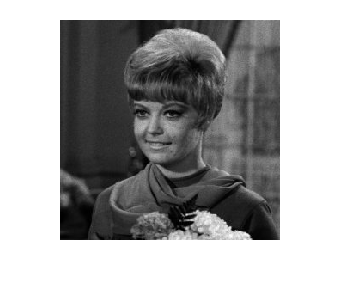

% 2 Execute os comandos abaixo. Descreva a função de cada linha (contextualizando com o visto na teoria).
% Usa a função imread para abrir a imagem
a = imread("pratica10.png" );
% Cria uma nova figura e exibe a imagem
figure, imshow(a);

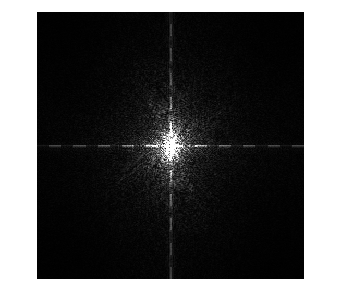

% A função padarray é usada para adicionar bordas na imagem, onde foi
% preenchido por zeros por padrão
b = padarray(a, size(a), "post");
% Converte a imagem b em double
c = im2double(b);
% Aplicado para calcular a transformada de Fourier 2d, transforma de
% domínio espacial para domínio da frequência
d = fft2(c);
% desloca as frequencias para que o componente fique no centro da imagem
d = fftshift(d);
% Exibe a imagem
figure, imshow(uint8(abs(d)));

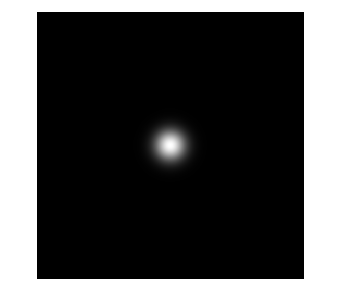


% Inicializada matriz h com zeros do mesmo tamanho da imagem b
h = zeros(size(b));
[n, m] = size(b);
% O loop duplo é utilizado para percorrer cada posição da matriz h e
% calcular o valor da função gaussiana utilizando a função H
for i = 1:n
    for j = 1:m
        h(i,j) = H(i,j,size(b),20);
    end
end
% Exibe o resultado
figure, imshow(im2uint8(h));

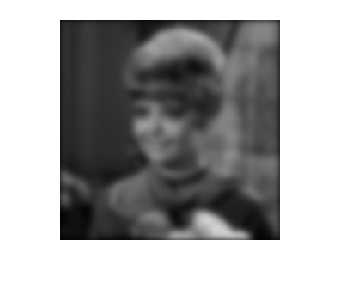


% O comando 
g = d.*h;
% multiplica o elemento por elemento a matriz d pela matriz h,
% Esse produto e usado posteriormente para fazer a filtragem no domínio da
% frequência

% Desloca o g para posição original
g = ifftshift(g);
% transformada inversa
at = ifft2(g);
at = abs(at);
[x, y] = size(a);
atc = at(1:x, 1:y);
figure, imshow(im2uint8(atc));

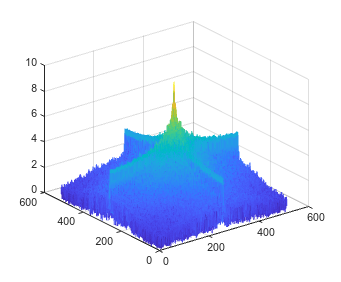


% tx e ty criam vetores que representam as coordenadas ao longo dos eixos
% x e y
tx = linspace(1, size(d, 1), size(d, 1))';
ty = linspace(1, size(d, 2), size(d, 2))';
% plota os valores da matriz d em relação a tx e ty
% O uso de log(1+abs(d)) permite uma melhor visualização da superfície, realçando detalhes na faixa dinâmica.
mesh(tx, ty, log(1+abs(d))');

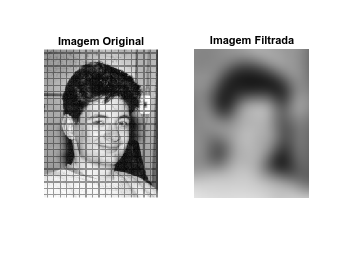


% 9. Resposta: O tipo de filtro aplicado e um filtro gaussiano, o parâmetro d0 da função
% H afeta o resultado ao determinar a largura da função. Um valor maior
% resultará uma função gaussiana mais ampla, o que causa o filtro ser mais
% suave no domínio da frequência

% 10. Resposta: Para eliminar ou reduzir o quadriculado na imagem, uma
% possível solução é aplicar um filtro passa-baixa no domínio da
% frequência, isso pode ser feito alterando os parâmetros da função H.
% Aumentar o valor de d0 irá suavizar as frequências altas, assim,
% reduzindo o quadriculado.
% Carregar a imagem "pratica10_vish.png"
image = imread('pratica10_vish.png');

% Converter a imagem para double
image_double = im2double(image);

% Aplicar um filtro passa-baixa para reduzir o quadriculado
d0 = 20; % Ajuste o valor de d0 conforme necessário
filtered_image = imgaussfilt(image_double, d0);

% Exibir a imagem original e a imagem filtrada
figure;
subplot(1,2,1);
imshow(image_double);
title('Imagem Original');
subplot(1,2,2);
imshow(filtered_image);
title('Imagem Filtrada');


% Salvar a imagem filtrada
imwrite(filtered_image, 'pratica10_vish_filtrada.png');

function res = D(u,v,s)
    res = sqrt((u-s(1)/2)^2+(v-s(2)/2)^2);
end

function res = H(u,v,s,d0)
    res = exp(-((D(u,v,s))^2)/(2*d0^2));
end
